# Figures of relative diffusivity

clear all 
close all

% Observations
obs_traj = load ('../data/traj_09_03_13_clean.mat');

% delete sections in the Scotia Sea.
obs_traj.Yc(obs_traj.Xc>-82) = NaN;
obs_traj.Xc(obs_traj.Xc>-82) = NaN;

% use forward differencing to estimate the velocity 
Unew = nan*obs_traj.Xc;
Vnew = nan*obs_traj.Xc;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(obs_traj.Xc)*cor.*cosd(obs_traj.Yc(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(obs_traj.Yc)*cor/dt; 

obs_traj.Uc = Unew; 
obs_traj.Vc = Vnew; 

% Models
d=[4, 10];

for i =1:length(d)
    [mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));
    
    % get the velocity from forward differencing (will be important for structure functions)
    Unew = nan*mod_traj(i).X;
    Vnew = nan*mod_traj(i).X;
    dt = 1*24*3600; 
    cor = 110*1e3; 
    
    Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
    Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 
    
    mod_traj(i).U = Unew; 
    mod_traj(i).V = Vnew; 
    
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-70) = NaN;
    
end

depth = -747.2217

depth = -1.4749e+03

% calculate separation time series 

sep_obs = calculate_seperation_timeseries(obs_traj);


% calc sep models

for i = 1
    for j =1:length(d)
        mod_sep_for_sep(j,i) = model_sep_calcs(mod_traj(j), [0, 50]*1e3); 
    end
end




%%define the distance axis 
gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));

%
diff_pres = 100; 
plevel = [500 1000 1800];

% obs
rd1_obs_deep_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(2:3),1); 
rd1_obs_shallow_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(1:2),1); 
rd2_obs_deep_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(2:3),2); 
rd2_obs_shallow_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(1:2),2); 
rd4_obs_deep_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(2:3),4); 
rd4_obs_shallow_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(1:2),4); 
rd6_obs_deep_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(2:3),6); 
rd6_obs_shallow_struct = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(1:2),6); 

% model 
rd1_mod_deep = rel_diff_inst_model(mod_sep_for_sep(2,1).sep, dist_bin,1); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



rd1_mod_shallow = rel_diff_inst_model(mod_sep_for_sep(1,1).sep, dist_bin,1); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



rd2_mod_deep = rel_diff_inst_model(mod_sep_for_sep(2,1).sep, dist_bin,2); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



rd2_mod_shallow = rel_diff_inst_model(mod_sep_for_sep(1,1).sep, dist_bin,2); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21




rd4_mod_deep = rel_diff_inst_model(mod_sep_for_sep(2,1).sep, dist_bin,4); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



rd4_mod_shallow = rel_diff_inst_model(mod_sep_for_sep(1,1).sep, dist_bin,4); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



rd6_mod_deep = rel_diff_inst_model(mod_sep_for_sep(2,1).sep, dist_bin,6); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



rd6_mod_shallow = rel_diff_inst_model(mod_sep_for_sep(1,1).sep, dist_bin,6); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



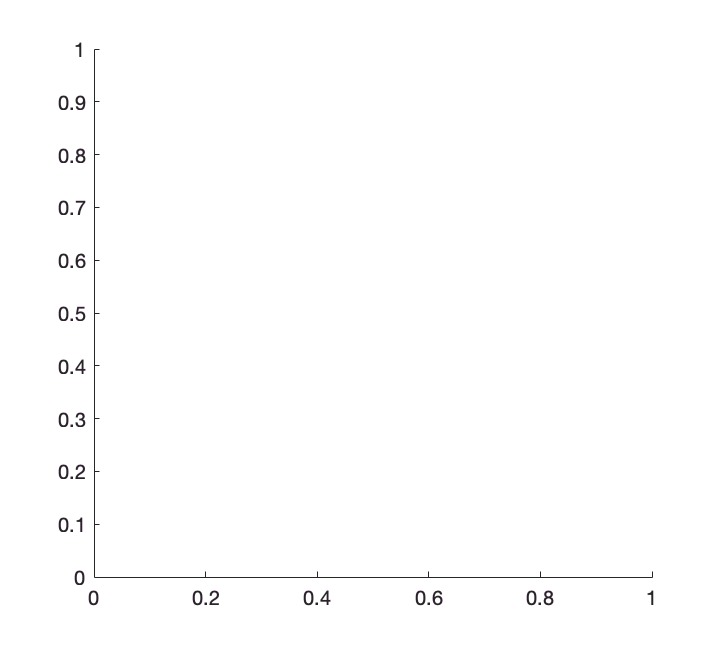

colors = get(gca,'ColorOrder');

col_num = [1,4; 2, 5];

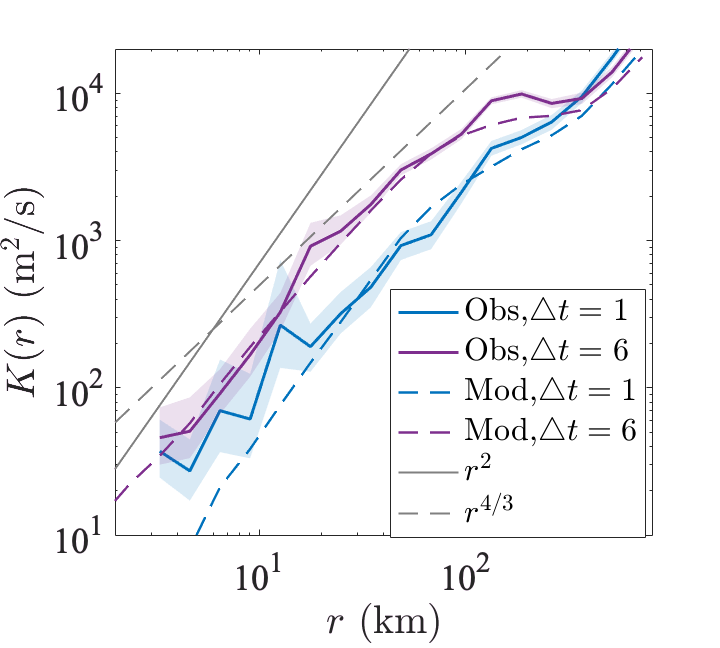

clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')

j=1; % shallow - j is for depth

h(1) = shadedErrorBar_log(dist_axis/1e3, rd1_obs_shallow_struct.rdmean, rd1_obs_shallow_struct.rdci, ...
            {'-','linewidth',1.5,'color', colors(col_num(j,1),:)}, 1);
hold all 
        
h(2) = shadedErrorBar_log(dist_axis/1e3, rd6_obs_shallow_struct.rdmean, rd6_obs_shallow_struct.rdci, ...
            {'-','linewidth',1.5,'color', colors(col_num(j,2),:)}, 1);     
        
g(1) = loglog(dist_axis/1e3, rd1_mod_shallow.rdmean,'--', 'linewidth',1.2,'color', colors(col_num(j,1),:));
g(2) = loglog(dist_axis/1e3, rd6_mod_shallow.rdmean,'--', 'linewidth',1.2,'color', colors(col_num(j,2),:));

r2 = loglog(dist_axis/1e3, 7e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 23e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([h(1).mainLine, h(2).mainLine, g ,r2, r43], ...
    {'Obs,$\triangle t=1$', 'Obs,$\triangle t = 6$' , ...
    'Mod,$\triangle t=1$', 'Mod,$\triangle t = 6$', ...
    '$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 800 10 2e4])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('rel_diff_sep_shallow.eps','-depsc', '-r400')

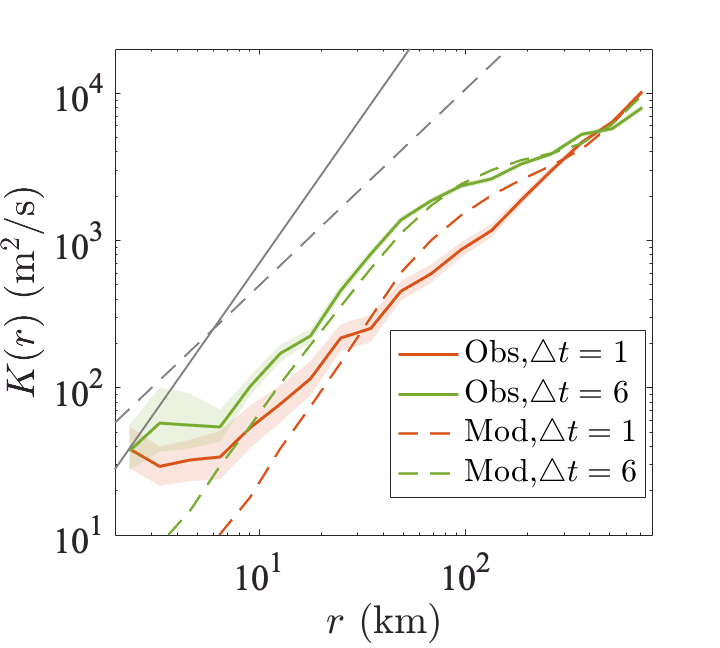

clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')

j=2; % shallow - j is for depth

h(1) = shadedErrorBar_log(dist_axis/1e3, rd1_obs_deep_struct.rdmean, rd1_obs_deep_struct.rdci, ...
            {'-','linewidth',1.5,'color', colors(col_num(j,1),:)}, 1);
hold all 
        
h(2) = shadedErrorBar_log(dist_axis/1e3, rd6_obs_deep_struct.rdmean, rd6_obs_deep_struct.rdci, ...
            {'-','linewidth',1.5,'color', colors(col_num(j,2),:)}, 1);     
        
g(1) = loglog(dist_axis/1e3, rd1_mod_deep.rdmean,'--', 'linewidth',1.2,'color', colors(col_num(j,1),:));
g(2) = loglog(dist_axis/1e3, rd6_mod_deep.rdmean,'--', 'linewidth',1.2,'color', colors(col_num(j,2),:));

r2 = loglog(dist_axis/1e3, 7e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 23e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([h(1).mainLine, h(2).mainLine, g ], ...
    {'Obs,$\triangle t=1$', 'Obs,$\triangle t = 6$' , ...
    'Mod,$\triangle t=1$', 'Mod,$\triangle t = 6$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 800 10 2e4])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('rel_diff_sep_deep.eps','-depsc', '-r400')

clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')

j=1; % shallow - j is for depth

h(1) = shadedErrorBar_log(dist_axis/1e3, rd6_obs_shallow_struct.rdXmean, rd6_obs_shallow_struct.rdXci, ...
            {'-','linewidth',1.5,'color', colors(col_num(j,1),:)}, 1);
hold all 
        
n=19; 
h(2) = shadedErrorBar_log(dist_axis(1:n)/1e3, rd6_obs_shallow_struct.rdYmean(1:n), rd6_obs_shallow_struct.rdYci(1:n,:), ...
            {'-','linewidth',1.5,'color', colors(col_num(j,2),:)}, 1);     
        
g(1) = loglog(dist_axis/1e3, rd6_mod_shallow.rdXmean,'--', 'linewidth',1.2,'color', colors(col_num(j,1),:));
g(2) = loglog(dist_axis/1e3, rd6_mod_shallow.rdYmean,'--', 'linewidth',1.2,'color', colors(col_num(j,2),:));

r2 = loglog(dist_axis/1e3, 7e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);

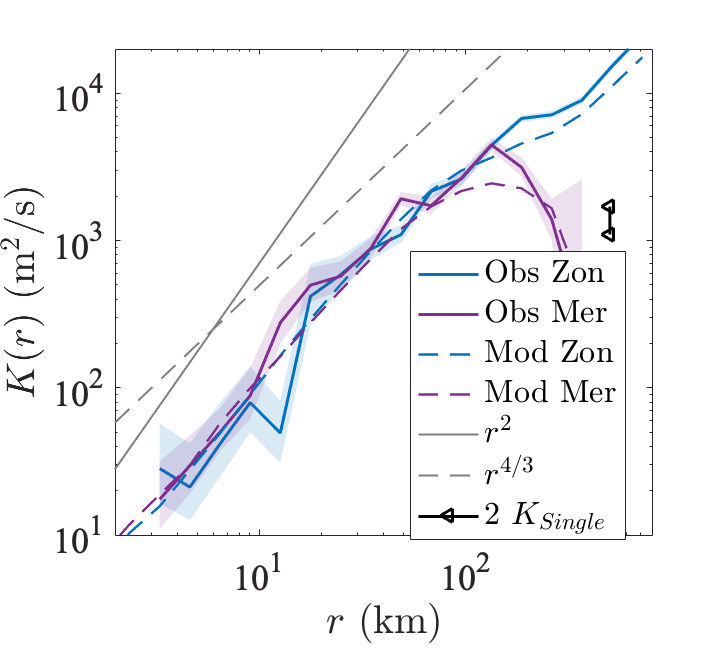

r43 = loglog(dist_axis/1e3, 23e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[550,850];
kbal = loglog(x, y, '<-','linewidth',1.5, 'color','k');


A = legend([h(1).mainLine, h(2).mainLine, g , r2 , r43, kbal], ...
    {'Obs Zon', 'Obs Mer' , ...
    'Mod Zon', 'Mod Mer', '$r^2$', '$r^{4/3}$', '2 $K_{Single}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 800 10 2e4])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('rel_diff_parts_sep_shallow.eps','-depsc', '-r400')

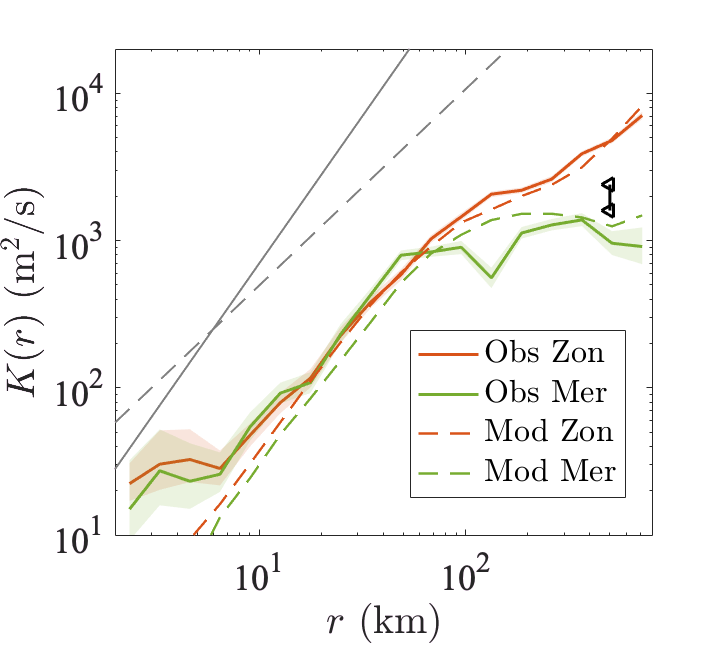

clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')

j=2; % shallow - j is for depth

h(1) = shadedErrorBar_log(dist_axis/1e3, rd6_obs_deep_struct.rdXmean, rd6_obs_deep_struct.rdXci, ...
            {'-','linewidth',1.5,'color', colors(col_num(j,1),:)}, 1);
hold all 
        
h(2) = shadedErrorBar_log(dist_axis/1e3, rd6_obs_deep_struct.rdYmean, rd6_obs_deep_struct.rdYci, ...
            {'-','linewidth',1.5,'color', colors(col_num(j,2),:)}, 1);     
        
g(1) = loglog(dist_axis/1e3, rd6_mod_deep.rdXmean,'--', 'linewidth',1.2,'color', colors(col_num(j,1),:));
g(2) = loglog(dist_axis/1e3, rd6_mod_deep.rdYmean,'--', 'linewidth',1.2,'color', colors(col_num(j,2),:));

r2 = loglog(dist_axis/1e3, 7e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 23e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[800,1200];
kbal = loglog(x, y, '<-','linewidth',1.5, 'color','k');

A = legend([h(1).mainLine, h(2).mainLine, g ], ...
    {'Obs Zon', 'Obs Mer' , ...
    'Mod Zon', 'Mod Mer'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 800 10 2e4])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('rel_diff_parts_sep_deep.eps','-depsc', '-r400')

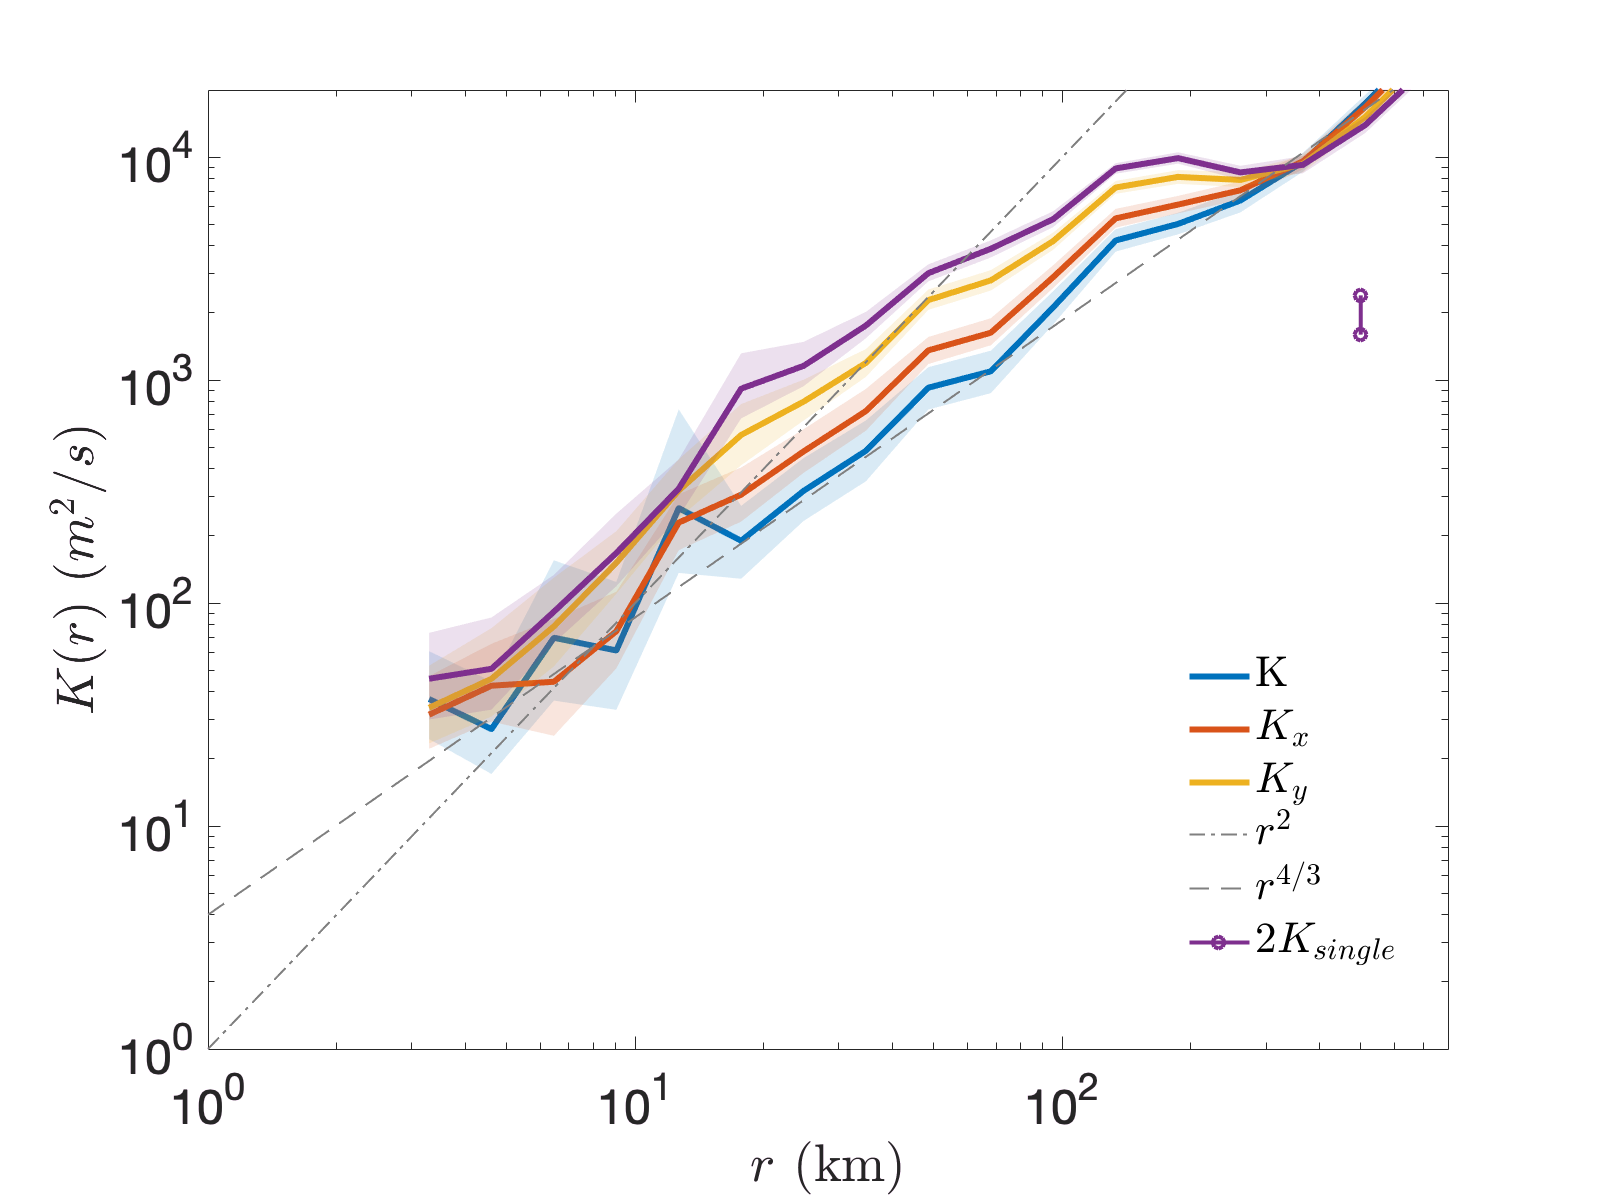

clear h g 
figure('rend','painters','pos',[10 10 800 600])
colors = get(gca,'ColorOrder');
col_num = [1,4; 2, 5];
%h(1) = shadedErrorBar_log(dist_axis/1e3, rd_obs_deep_mean, rd_obs_deep_ci, ...
%            {'-','linewidth',3,'color', colors(1,:)}, 1);
h(1) = shadedErrorBar_log(dist_axis/1e3, rd1_obs_shallow_struct.rdmean, rd1_obs_shallow_struct.rdci, ...
            {'-','linewidth',3,'color', colors(1,:)}, 1);
hold all 
h(2) = shadedErrorBar_log(dist_axis/1e3, rd2_obs_shallow_struct.rdmean, rd2_obs_shallow_struct.rdci, ...
            {'-','linewidth',3,'color', colors(2,:)}, 1);

h(3) = shadedErrorBar_log(dist_axis/1e3, rd4_obs_shallow_struct.rdmean, rd4_obs_shallow_struct.rdci, ...
            {'-','linewidth',3,'color', colors(3,:)}, 1);
        
h(4) = shadedErrorBar_log(dist_axis/1e3, rd6_obs_shallow_struct.rdmean, rd6_obs_shallow_struct.rdci, ...
            {'-','linewidth',3,'color', colors(4,:)}, 1);            

r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-.','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 4e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[800,1200];
kbal = loglog(x, y, 'o-', 'linewidth',2);

A = legend([h(1).mainLine, h(2).mainLine, h(3).mainLine,r2, r43, kbal], ...
    {'K','$K_x$','$K_y$','$r^2$','$r^{4/3}$','$2K_{single}$'} ...
    , 'Interpreter','Latex');
legend boxoff
set(A, 'location','best') 
set(gca, 'fontsize', 24) 

axis([1 800 1 2e4])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ ($m^{2}/s$)', 'Interpreter','Latex')

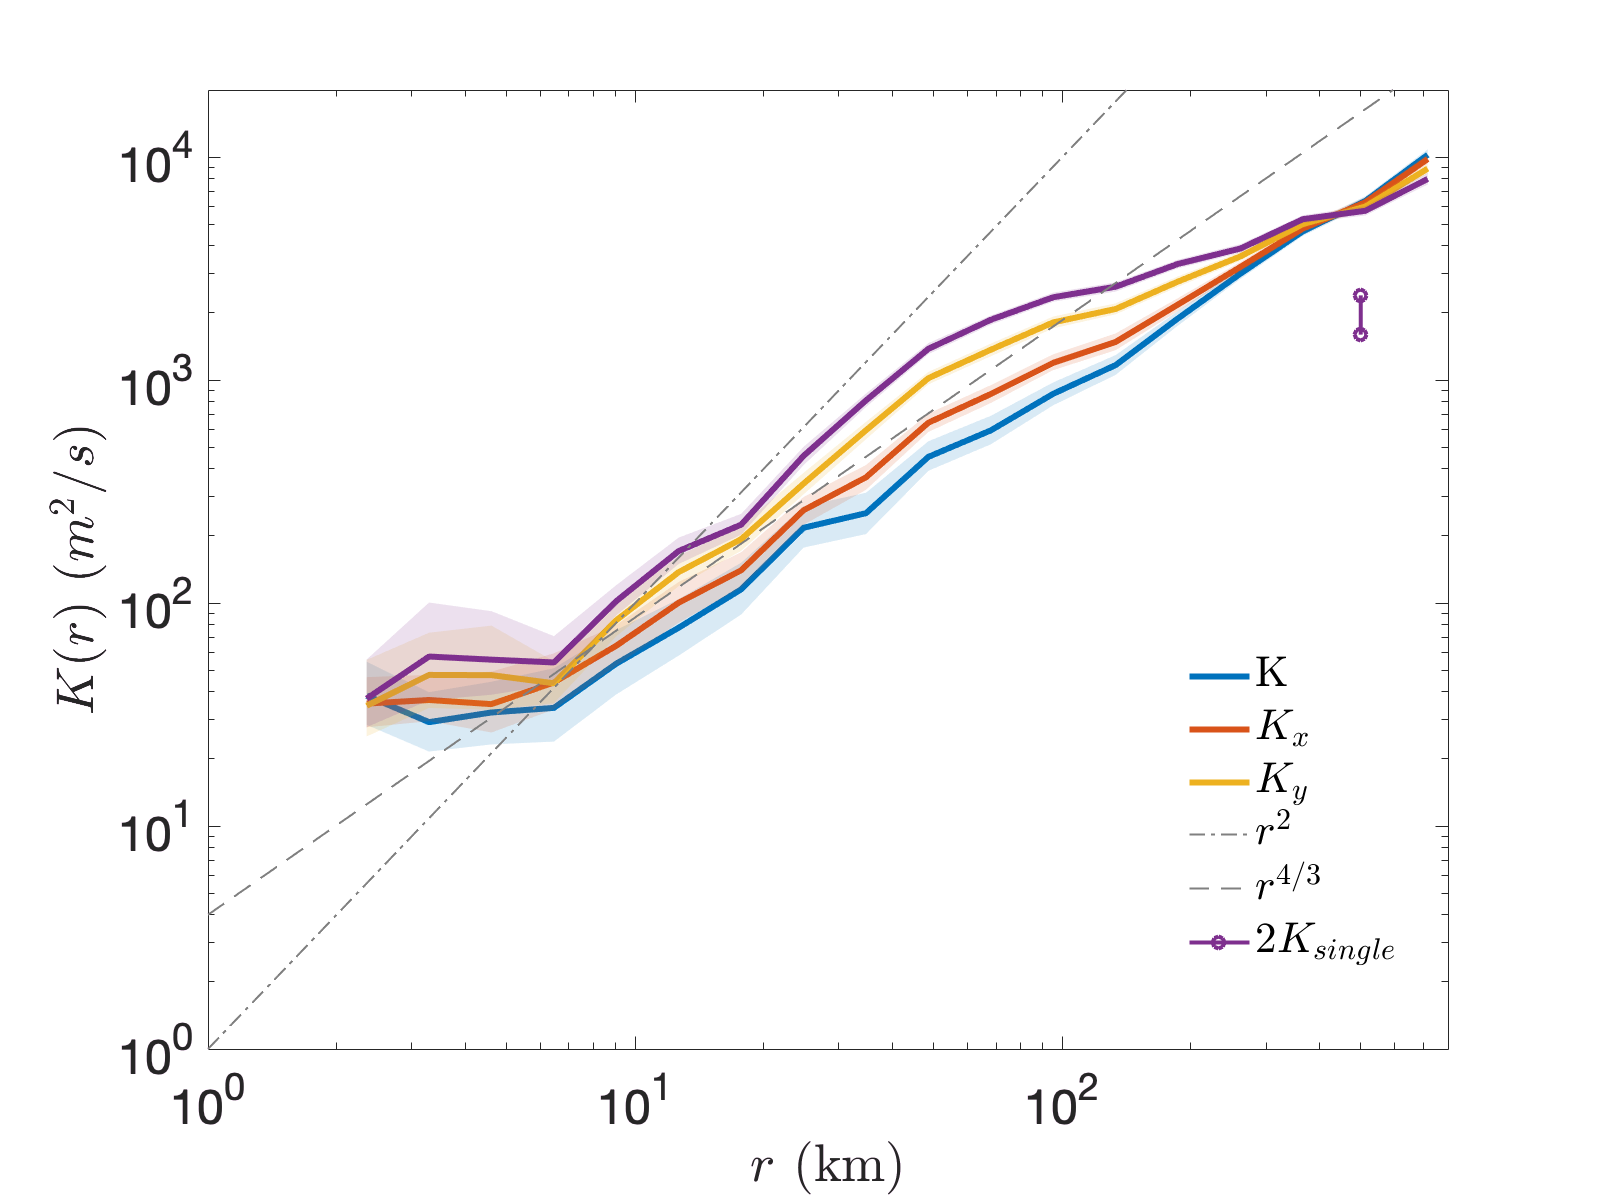

clear h g 
figure('rend','painters','pos',[10 10 800 600])
colors = get(gca,'ColorOrder');
col_num = [1,4; 2, 5];
%h(1) = shadedErrorBar_log(dist_axis/1e3, rd_obs_deep_mean, rd_obs_deep_ci, ...
%            {'-','linewidth',3,'color', colors(1,:)}, 1);
h(1) = shadedErrorBar_log(dist_axis/1e3, rd1_obs_deep_struct.rdmean, rd1_obs_deep_struct.rdci, ...
            {'-','linewidth',3,'color', colors(1,:)}, 1);
hold all 
h(2) = shadedErrorBar_log(dist_axis/1e3, rd2_obs_deep_struct.rdmean, rd2_obs_deep_struct.rdci, ...
            {'-','linewidth',3,'color', colors(2,:)}, 1);

h(3) = shadedErrorBar_log(dist_axis/1e3, rd4_obs_deep_struct.rdmean, rd4_obs_deep_struct.rdci, ...
            {'-','linewidth',3,'color', colors(3,:)}, 1);
        
h(4) = shadedErrorBar_log(dist_axis/1e3, rd6_obs_deep_struct.rdmean, rd6_obs_deep_struct.rdci, ...
            {'-','linewidth',3,'color', colors(4,:)}, 1);            

r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-.','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 4e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[800,1200];
kbal = loglog(x, y, 'o-', 'linewidth',2);

A = legend([h(1).mainLine, h(2).mainLine, h(3).mainLine,r2, r43, kbal], ...
    {'K','$K_x$','$K_y$','$r^2$','$r^{4/3}$','$2K_{single}$'} ...
    , 'Interpreter','Latex');
legend boxoff
set(A, 'location','best') 
set(gca, 'fontsize', 24) 

axis([1 800 1 2e4])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ ($m^{2}/s$)', 'Interpreter','Latex')

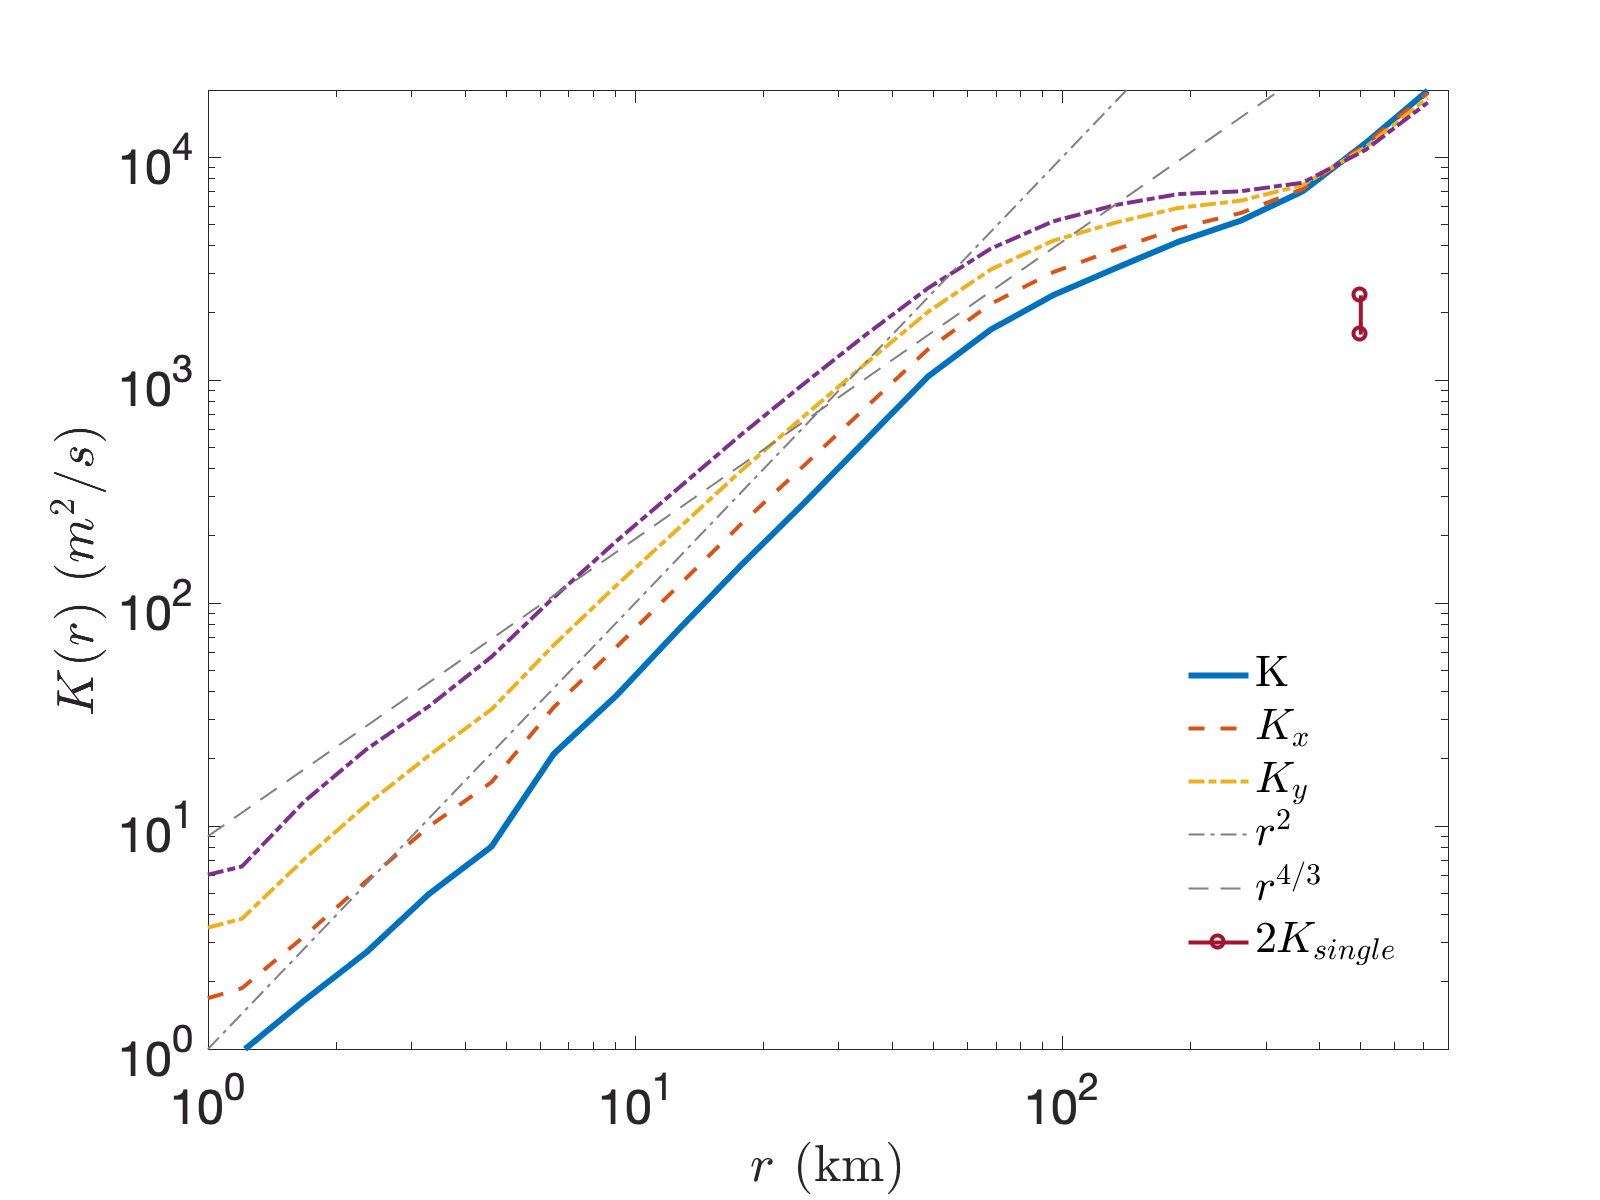

% model deep 

clear h g 
figure('rend','painters','pos',[10 10 800 600])
g(1) = loglog(dist_axis/1e3, rd1_mod_shallow.rdmean,'-', 'linewidth',3,'color', colors(1,:));
hold all
g(2) = loglog(dist_axis/1e3, rd2_mod_shallow.rdmean,'--', 'linewidth',2,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd4_mod_shallow.rdmean,'-.', 'linewidth',2,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd6_mod_shallow.rdmean,'-.', 'linewidth',2,'color', colors(4,:));

r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-.','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 9e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[800,1200];
kbal = loglog(x, y, 'o-', 'linewidth',2);

A = legend([g(1), g(2), g(3),r2, r43, kbal], ...
    {'K','$K_x$','$K_y$','$r^2$','$r^{4/3}$','$2K_{single}$'} ...
    , 'Interpreter','Latex');
legend boxoff
set(A, 'location','best') 
set(gca, 'fontsize', 24) 

axis([1 800 1 2e4])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ ($m^{2}/s$)', 'Interpreter','Latex')

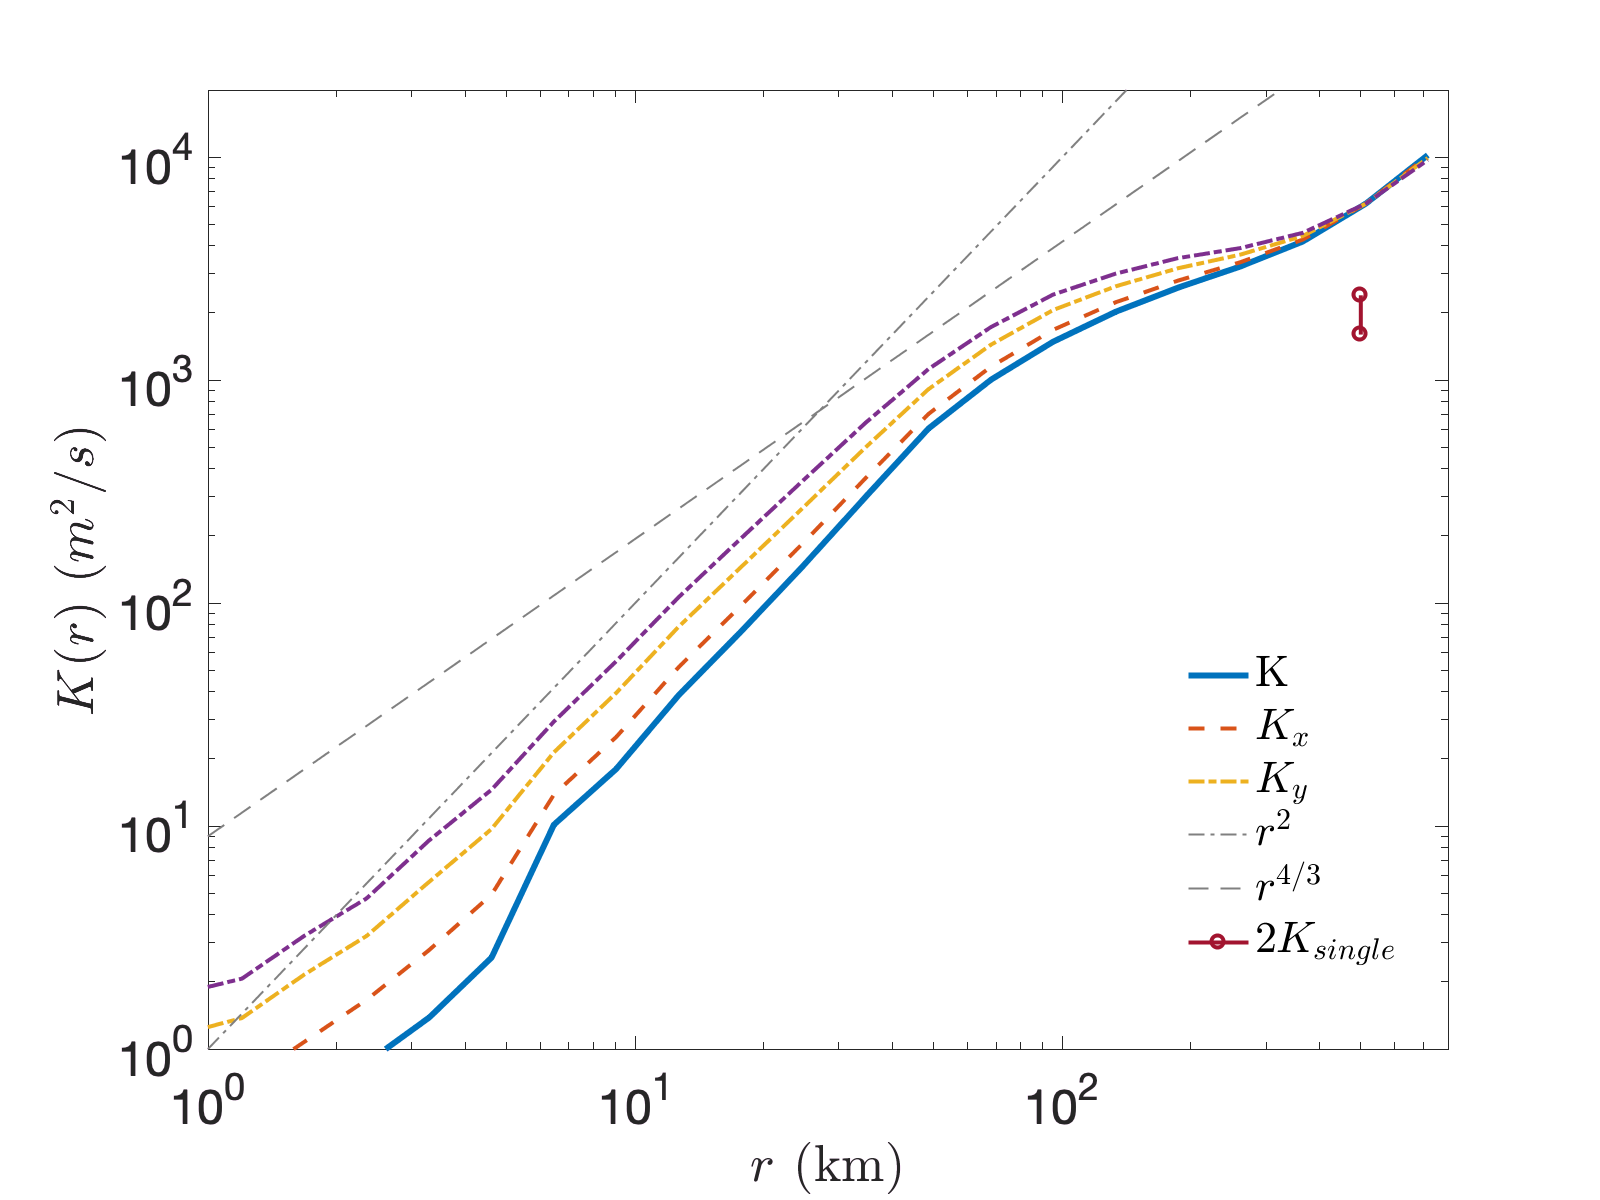

% model deep 

clear h g 
figure('rend','painters','pos',[10 10 800 600])
g(1) = loglog(dist_axis/1e3, rd1_mod_deep.rdmean,'-', 'linewidth',3,'color', colors(1,:));
hold all
g(2) = loglog(dist_axis/1e3, rd2_mod_deep.rdmean,'--', 'linewidth',2,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd4_mod_deep.rdmean,'-.', 'linewidth',2,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd6_mod_deep.rdmean,'-.', 'linewidth',2,'color', colors(4,:));

r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-.','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 9e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[800,1200];
kbal = loglog(x, y, 'o-', 'linewidth',2);

A = legend([g(1), g(2), g(3),r2, r43, kbal], ...
    {'K','$K_x$','$K_y$','$r^2$','$r^{4/3}$','$2K_{single}$'} ...
    , 'Interpreter','Latex');
legend boxoff
set(A, 'location','best') 
set(gca, 'fontsize', 24) 

axis([1 800 1 2e4])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ ($m^{2}/s$)', 'Interpreter','Latex')

% calculate the dispersion for the time based metrics 

% Distance pairs
distance_class(1).dist = [10,15]*1e3;
distance_class(2).dist = [30,35]*1e3;

pdiff  = 200;
ndays = 100; 
%% get the right pairs
for i =1:length(distance_class)
    for j=1:length(plevel)-1
        [obs_pairs(j,i), obs_sep(j,i)] = find_pairs(sep_obs, distance_class(i).dist, [plevel(j) plevel(j+1)], pdiff, ndays);
    end
end

% calc sep models
for i = 1:length(distance_class)
    for j =1:length(d)
        mod_sep(j,i) = model_sep_calcs(mod_traj(j), distance_class(i).dist); 
    end
end



% dispersion
% model 
for i =1:length(distance_class)
    for j =1:length(d)       
            Mod_disp(j,i) = rel_disp(mod_sep(j,i).sep, ndays);
    end
end

% obs
for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n = 1:500
            y = randsample(obs_pairs(j,i),obs_pairs(j,i),true);
            Obsbs(n,j,i) = rel_disp(obs_sep(j,i).sep(y), ndays);
        end
    end
end


% relative diffusivity

for i =1:length(distance_class)
    for j =1:length(d)       
            Mod_rel_diff1(j,i) = rel_diff(Mod_disp(j,i).avdisp, ndays,1);
            K_mod_1(:,j,i) = Mod_rel_diff1(j,i).diff; 
            r_mod_1(:,j,i) = Mod_rel_diff1(j,i).r; 
            Mod_rel_diff2(j,i) = rel_diff(Mod_disp(j,i).avdisp, ndays,2);
            K_mod_2(:,j,i) = Mod_rel_diff2(j,i).diff; 
            r_mod_2(:,j,i) = Mod_rel_diff2(j,i).r;
            Mod_rel_diff4(j,i) = rel_diff(Mod_disp(j,i).avdisp, ndays,4);
            K_mod_4(:,j,i) = Mod_rel_diff4(j,i).diff; 
            r_mod_4(:,j,i) = Mod_rel_diff4(j,i).r;
            Mod_rel_diff6(j,i) = rel_diff(Mod_disp(j,i).avdisp, ndays,6);
            K_mod_6(:,j,i) = Mod_rel_diff6(j,i).diff; 
            r_mod_6(:,j,i) = Mod_rel_diff6(j,i).r;
    end
end


for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n = 1:500
            Obs_rel_diff1(n,j,i) = rel_diff(Obsbs(n,j,i).avdisp, ndays, 1);
            K_obs_1(:,n,j,i) = Obs_rel_diff1(n,j,i).diff; 
            r_obs_1(:,n,j,i) = Obs_rel_diff1(n,j,i).r;
            Obs_rel_diff2(n,j,i) = rel_diff(Obsbs(n,j,i).avdisp, ndays, 2);
            K_obs_2(:,n,j,i) = Obs_rel_diff2(n,j,i).diff; 
            r_obs_2(:,n,j,i) = Obs_rel_diff2(n,j,i).r;
            Obs_rel_diff4(n,j,i) = rel_diff(Obsbs(n,j,i).avdisp, ndays, 4);
            K_obs_4(:,n,j,i) = Obs_rel_diff4(n,j,i).diff; 
            r_obs_4(:,n,j,i) = Obs_rel_diff4(n,j,i).r;
            Obs_rel_diff6(n,j,i) = rel_diff(Obsbs(n,j,i).avdisp, ndays, 6);
            K_obs_6(:,n,j,i) = Obs_rel_diff6(n,j,i).diff; 
            r_obs_6(:,n,j,i) = Obs_rel_diff6(n,j,i).r;
        end
    end
end

[K_obs_1mean, K_obs_1ci] = errbar4shadedlog(K_obs_1);
r_obs_1mean = squeeze(nanmean(r_obs_1,2));
[K_obs_2mean, K_obs_2ci] = errbar4shadedlog(K_obs_2);
r_obs_2mean = squeeze(nanmean(r_obs_2,2));
[K_obs_4mean, K_obs_4ci] = errbar4shadedlog(K_obs_4);
r_obs_4mean = squeeze(nanmean(r_obs_4,2));
[K_obs_6mean, K_obs_6ci] = errbar4shadedlog(K_obs_6);
r_obs_6mean = squeeze(nanmean(r_obs_6,2));

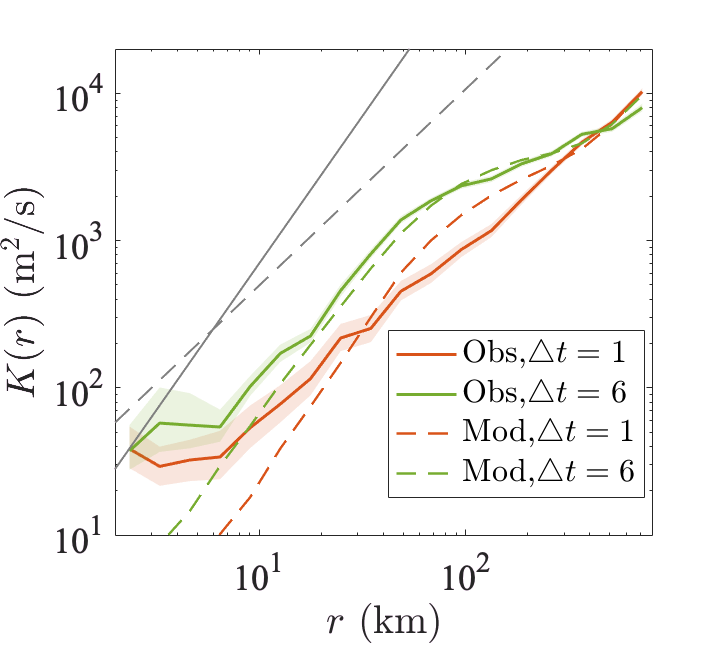

% model deep 

clear h g 
figure('rend','painters','pos',[10 10 800 600])

for i =1:length(distance_class)
    for j =1%:length(d)
        loglog(r_mod_1(:,j,i)/1e3, K_mod_1(:,j,i),'-', 'linewidth',3,'color', colors(1,:));
        hold all
        loglog(r_mod_2(:,j,i)/1e3, K_mod_2(:,j,i),'-', 'linewidth',3,'color', colors(2,:));
        loglog(r_mod_4(:,j,i)/1e3, K_mod_4(:,j,i),'-', 'linewidth',3,'color', colors(3,:));
        loglog(r_mod_6(:,j,i)/1e3, K_mod_6(:,j,i),'-', 'linewidth',3,'color', colors(4,:));
    end
end

r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-.','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 9e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[800,1200];
kbal = loglog(x, y, 'o-', 'linewidth',2);

%A = legend([g(1), g(2), g(3),r2, r43, kbal], ...
%    {'K','$K_x$','$K_y$','$r^2$','$r^{4/3}$','$2K_{single}$'} ...
%    , 'Interpreter','Latex');
%legend boxoff
set(A, 'location','best') 

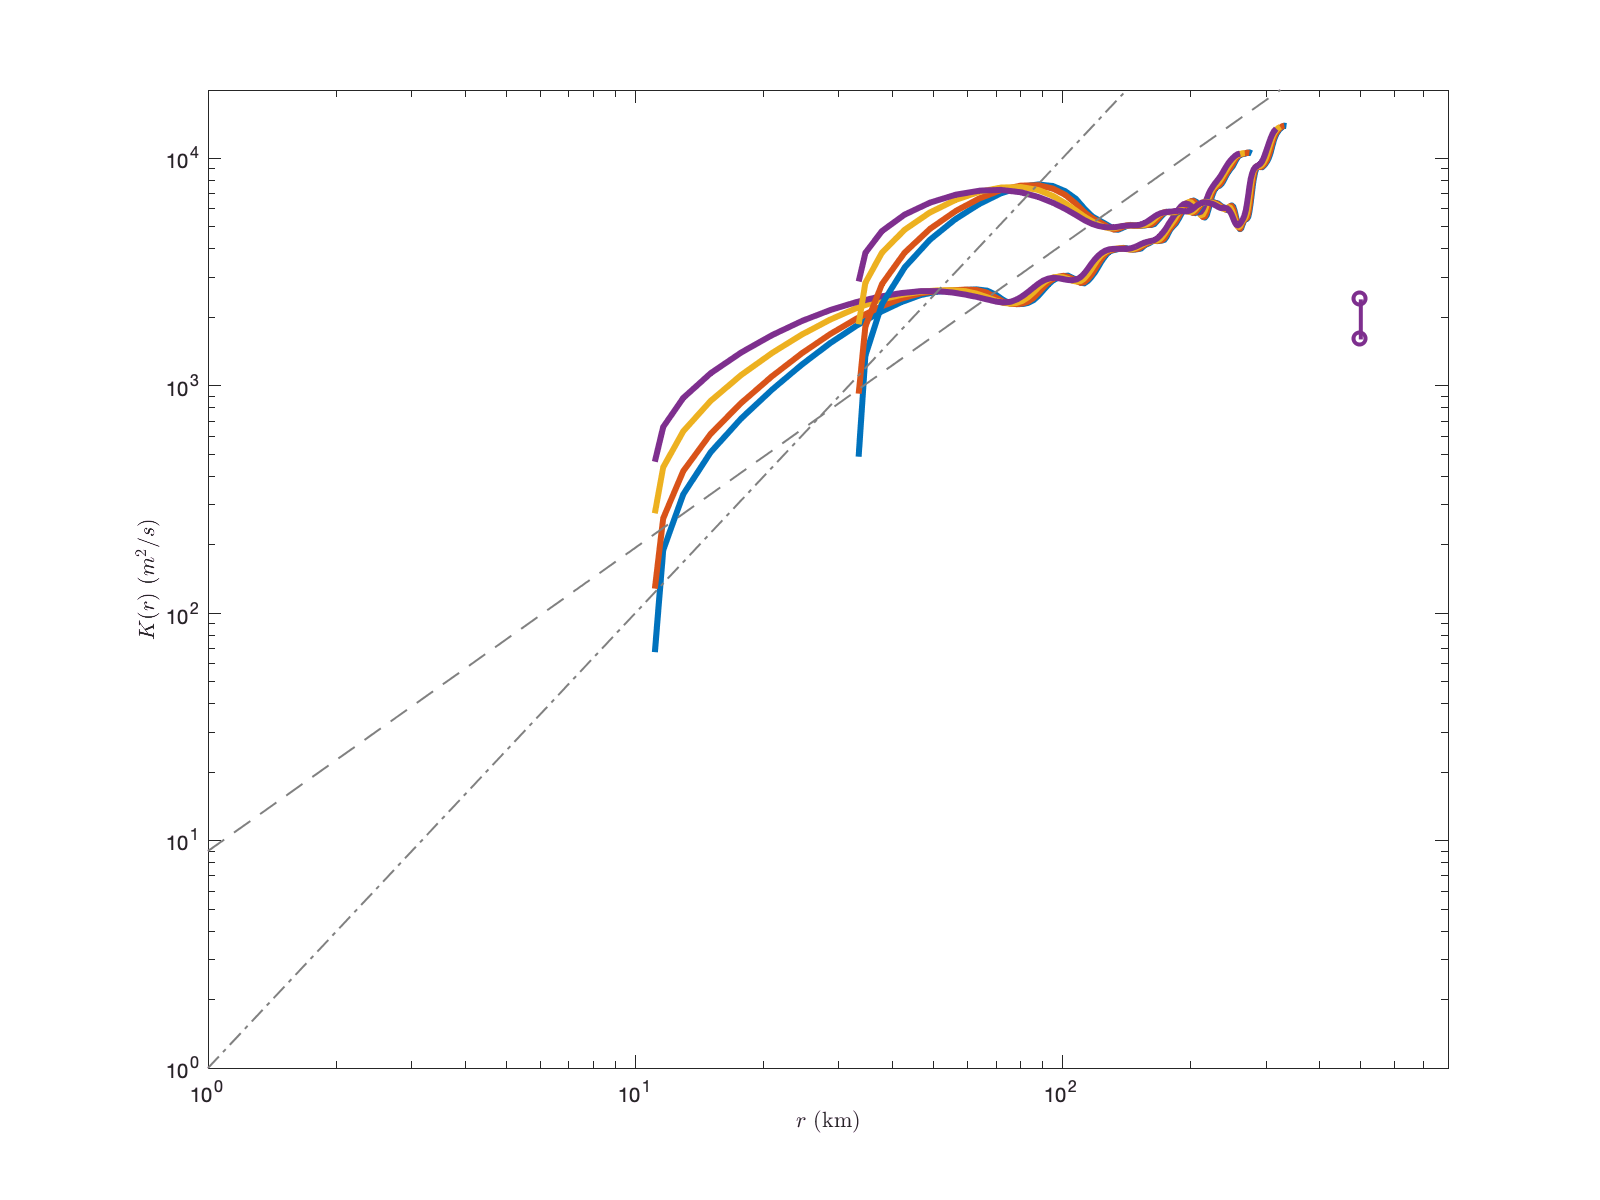


axis([1 800 1 2e4])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ ($m^{2}/s$)', 'Interpreter','Latex')

% model deep 

clear h g 
figure('rend','painters','pos',[10 10 800 600])
for i =1:length(distance_class)
    for j =2%:length(d)
        
        loglog(r_mod_1(:,j,i)/1e3, K_mod_1(:,j,i),'-', 'linewidth',3,'color', colors(1,:));
        hold all
        loglog(r_mod_2(:,j,i)/1e3, K_mod_2(:,j,i),'-', 'linewidth',3,'color', colors(2,:));
        loglog(r_mod_4(:,j,i)/1e3, K_mod_4(:,j,i),'-', 'linewidth',3,'color', colors(3,:));
        loglog(r_mod_6(:,j,i)/1e3, K_mod_6(:,j,i),'-', 'linewidth',3,'color', colors(4,:));
    end
end

r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-.','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 9e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

x= [500, 500]; 
y = 2*[800,1200];
kbal = loglog(x, y, 'o-', 'linewidth',2);

%A = legend([g(1), g(2), g(3),r2, r43, kbal], ...
%    {'K','$K_x$','$K_y$','$r^2$','$r^{4/3}$','$2K_{single}$'} ...
%    , 'Interpreter','Latex');
legend boxoff
set(A, 'location','best') 

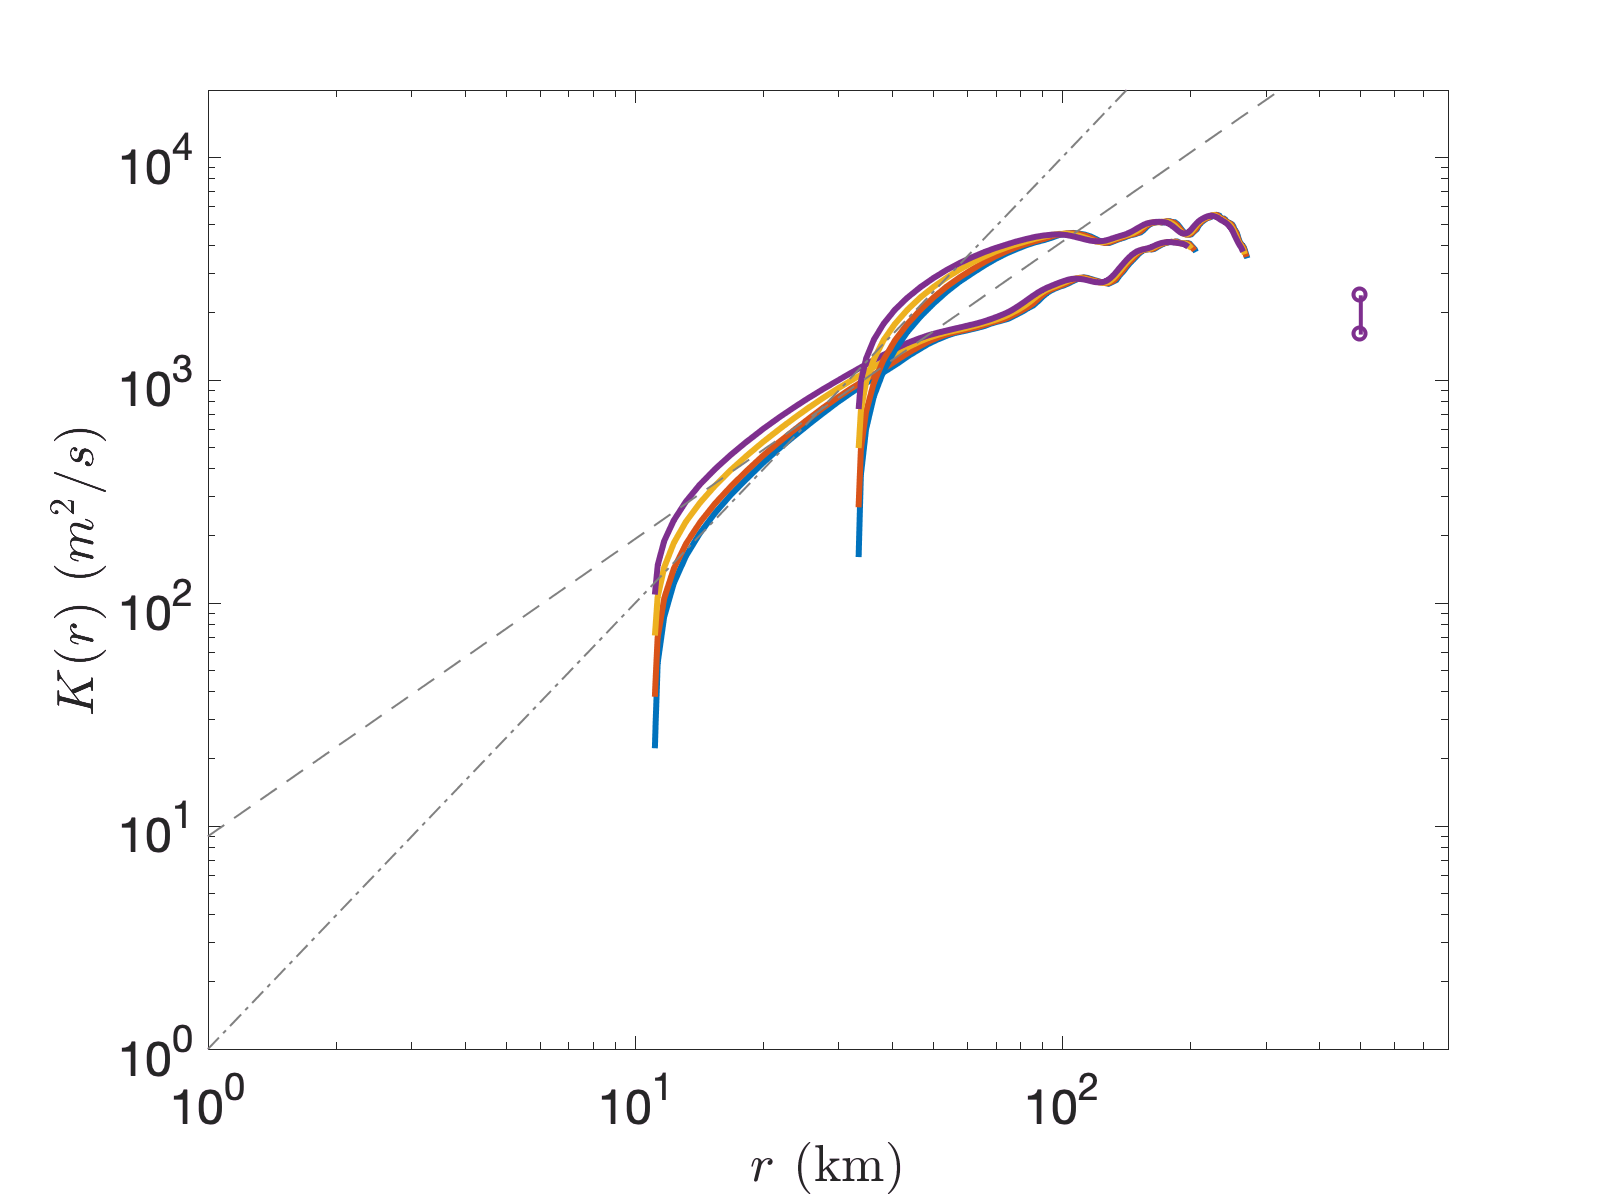

set(gca, 'fontsize', 24) 

axis([1 800 1 2e4])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ ($m^{2}/s$)', 'Interpreter','Latex')

% model deep 

clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')
for i =1:length(distance_class)
    for j =2%:length(d)
        %h(1) = shadedErrorBar_log(r_obs_1mean(:,j,i)/1e3, K_obs_1mean(:,j,i), K_obs_1ci(:,j,i), ...
        %    {'-','linewidth',3,'color', colors(1,:)}, 1);
        %hold all
        %loglog(r_obs_1mean(:,j,i)/1e3, K_obs_1mean(:,j,i),'-', 'linewidth',3,'color', colors(1,:));
        %hold all
        %loglog(r_obs_2mean(:,j,i)/1e3, K_obs_2mean(:,j,i),'-', 'linewidth',3,'color', colors(2,:));
        %loglog(r_obs_4mean(:,j,i)/1e3, K_obs_4mean(:,j,i),'-', 'linewidth',3,'color', colors(3,:));
        h(i) = shadedErrorBar_log(r_obs_6mean(:,j,i)/1e3, K_obs_6mean(:,j,i), K_obs_6ci(:,j,i), ...
            {'-','linewidth',1.5,'color', colors(col_num(j,i),:)}, 1);
        hold all
        %loglog(r_mod_1(:,j,i)/1e3, K_mod_1(:,j,i),'-', 'linewidth',3,'color', colors(1,:));
        %hold all
        %loglog(r_mod_2(:,j,i)/1e3, K_mod_2(:,j,i),'-', 'linewidth',3,'color', colors(2,:));
        %loglog(r_mod_4(:,j,i)/1e3, K_mod_4(:,j,i),'-', 'linewidth',3,'color', colors(3,:));
        g(i) = loglog(r_mod_6(:,j,i)/1e3, K_mod_6(:,j,i),'--', 'linewidth',1.2,'color', colors(col_num(j,i),:));
    end
end

%r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-.','color', [0.5 0.5 0.5], 'linewidth',1);
%r43 = loglog(dist_axis/1e3, 9e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);
r2 = loglog(dist_axis/1e3, 7e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 23e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);

A = legend([h(1).mainLine, h(2).mainLine, g(1), g(2)], ...
    {'Obs 10-15km','Obs 30-35km','Mod 11km','Mod 33km','$r^2$', '$r^{4/3}$'} ...
    , 'Interpreter','Latex');

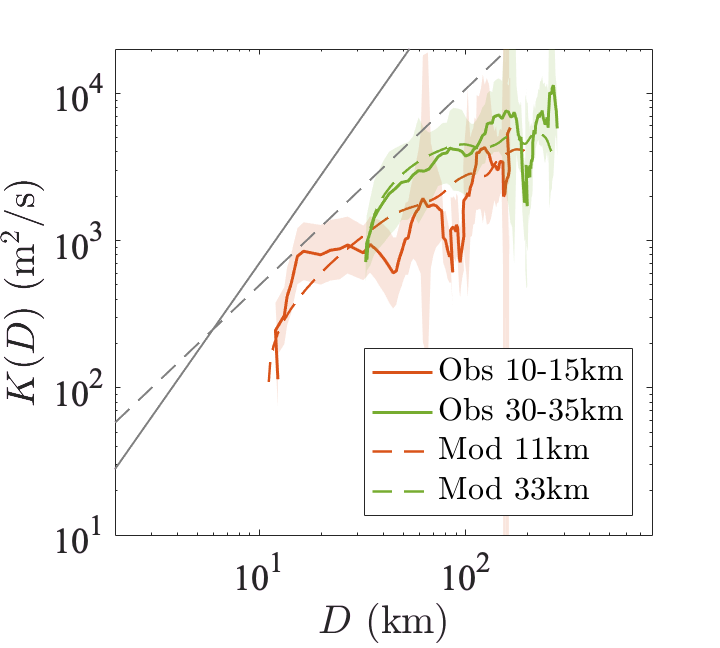

set(A, 'location','southeast') 
set(gca, 'fontsize', 18, 'fontname', 'times') 

axis([2 800 10 2e4])
%axis([10 300 90 2e4])

xlabel('$D$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (D)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('rel_diff_time_deep.eps','-depsc', '-r400')

% look at a plot of dT vs D on relative diffusivity
dt = [1,2,3,4,6,8,10,15,20,40,60];


clear rel_diff_obs_deep_struct
for i =1:length(dt)
    rel_diff_obs_deep_struct(i) = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(2:3),dt(i));
end

clear rel_diff_obs_shallow_struct
for i =1:length(dt)
    rel_diff_obs_shallow_struct(i) = rel_diff_inst(sep_obs, dist_bin, diff_pres, plevel(1:2),dt(i));
end

%rel_diff_inst_model(mod_sep_for_sep(2,1).sep, dist_bin,1); 
clear rel_diff_mod_deep_struct
for i =1:length(dt)
    rel_diff_mod_deep_struct(i) = rel_diff_inst_model(mod_sep_for_sep(2,1).sep, dist_bin,dt(i)); 
end

clear rel_diff_mod_shallow_struct
for i =1:length(dt)
    rel_diff_mod_shallow_struct(i) = rel_diff_inst_model(mod_sep_for_sep(1,1).sep, dist_bin,dt(i)); 
end

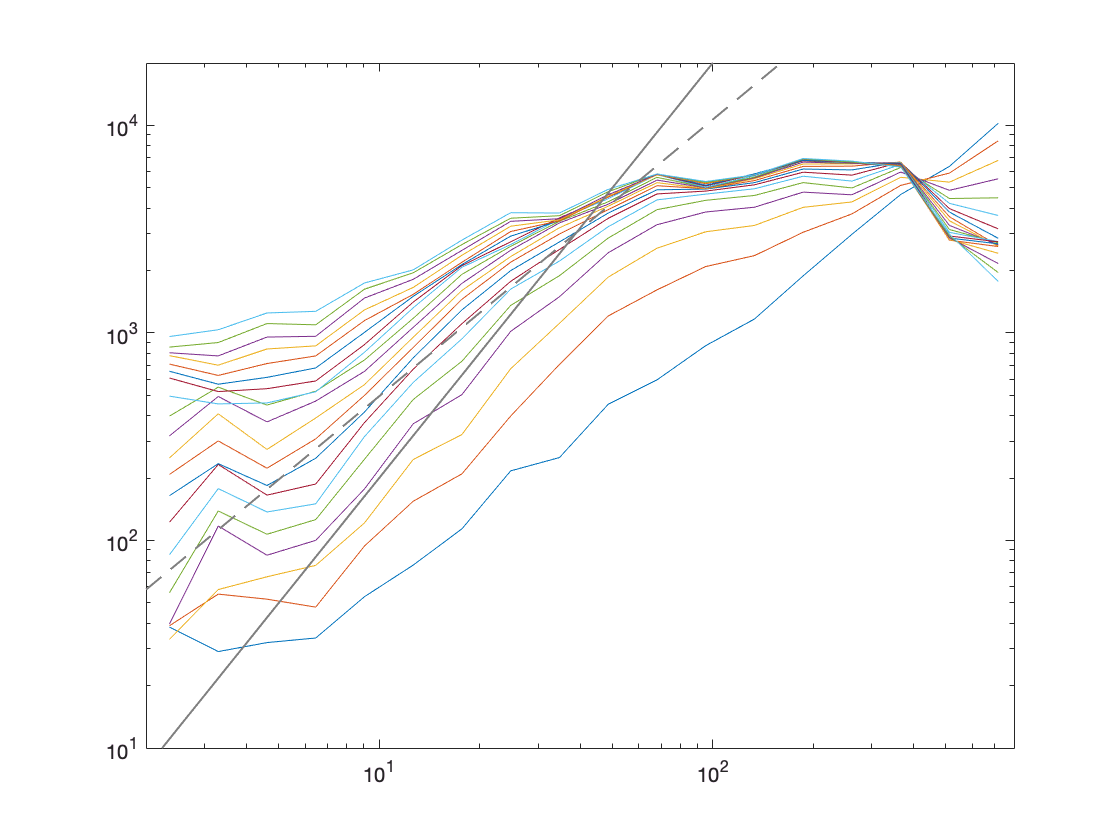

figure
for i = 1:length(dt)
    loglog(dist_axis/1e3, rel_diff_obs_deep_struct(i).rdmean)
    hold all 
end
loglog(dist_axis/1e3, 2e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
loglog(dist_axis/1e3, 23e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);
axis([2 800 10 2e4])

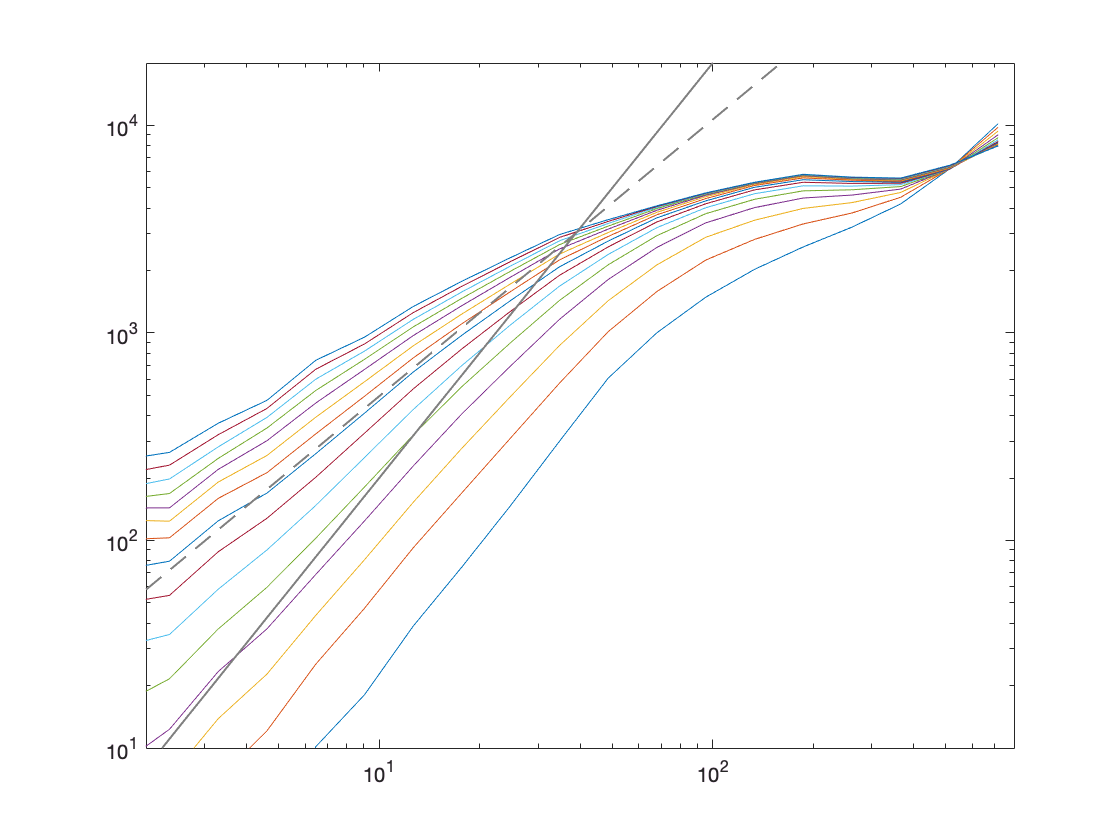

figure
for i = 1:length(rel_diff_mod_deep_struct)
    loglog(dist_axis/1e3, rel_diff_mod_deep_struct(i).rdmean)
    hold all 
end
loglog(dist_axis/1e3, 2e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
loglog(dist_axis/1e3, 23e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);
axis([2 800 10 2e4])

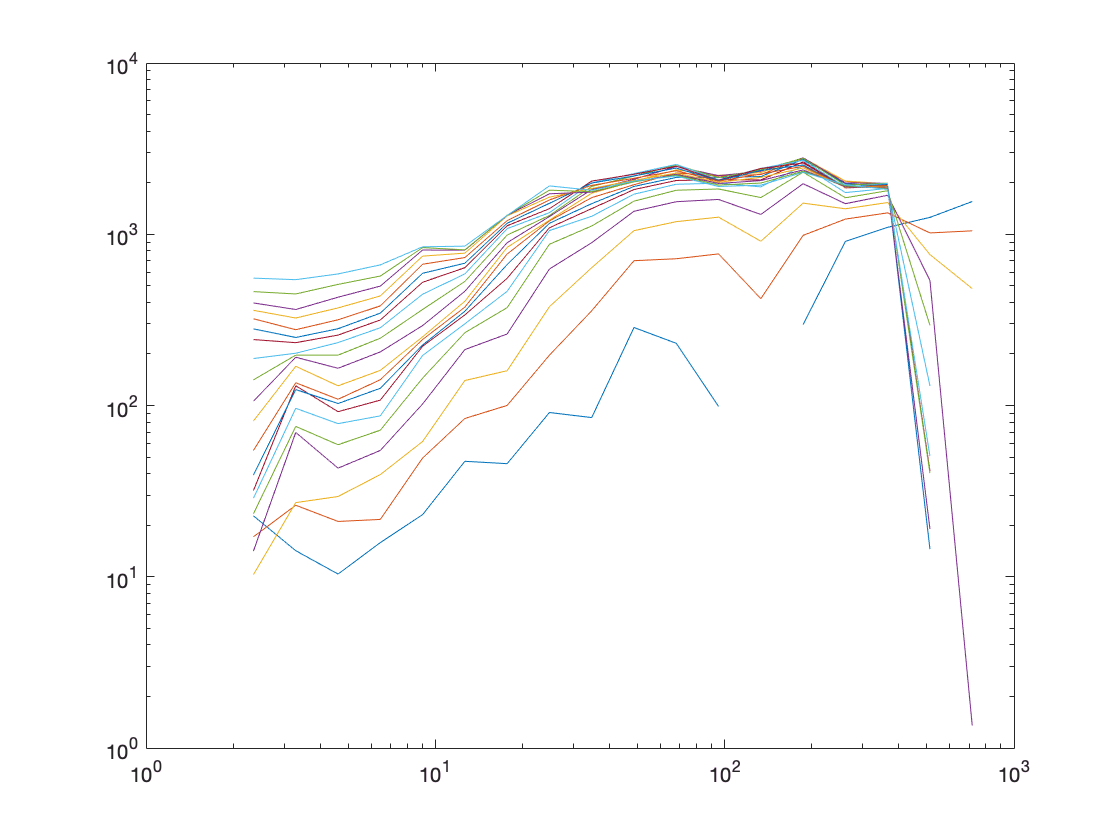

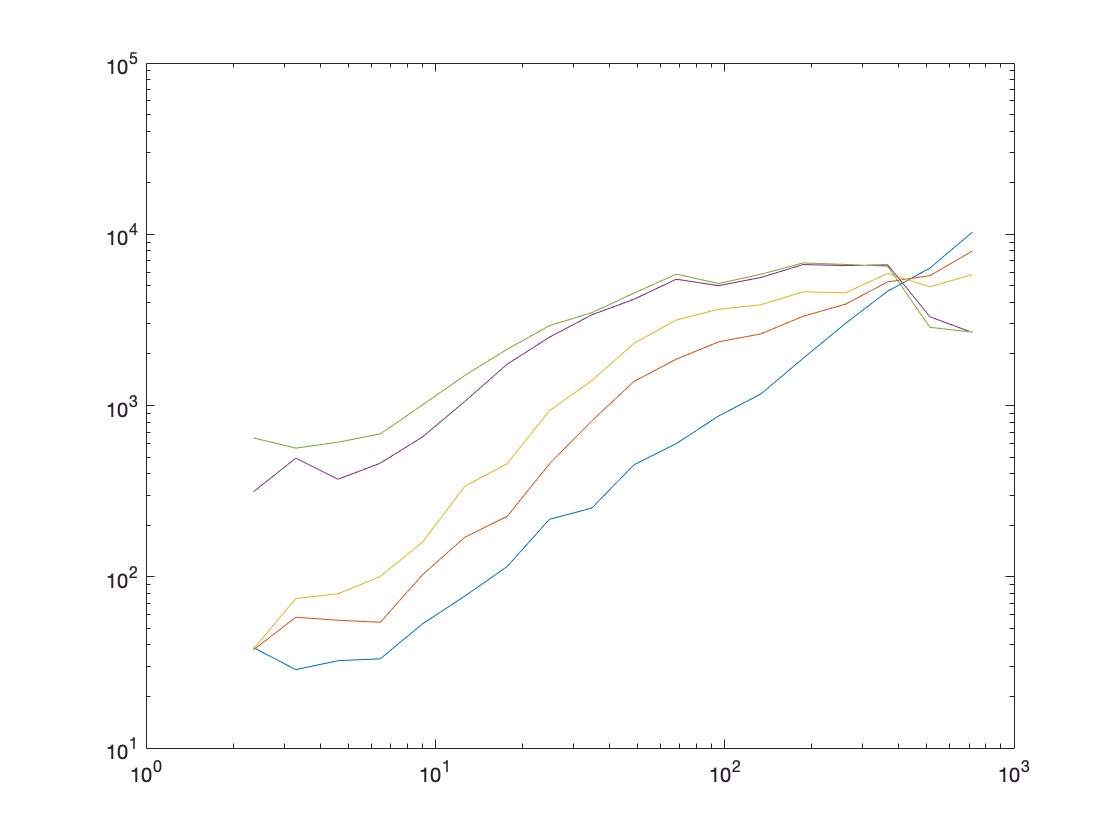

figure
for i = 1:length(dt)
    loglog(dist_axis/1e3, rel_diff_obs_deep_struct(i).rdYmean)
    hold all 
end

% fit a line to see how the slope varies. 

id = find(dist_axis/1e3>6 & dist_axis/1e3<50); 

x = log(dist_axis(id))'; 
clear slope_mod slope_obs
for i = 1:length(dt)
    y = log(rel_diff_obs_deep_struct(i).rdmean(id)); 
    f = fit(x,y,'poly1'); 
    slope_obs(i) = f.p1; 
    y = log(rel_diff_mod_deep_struct(i).rdmean(id)); 
    f = fit(x,y','poly1'); 
    slope_mod(i) = f.p1;
end


id = find(dist_axis/1e3>6 & dist_axis/1e3<50); 

x = log(dist_axis(id))'; 
%clear slope_mod slope_obs
for i = 1:length(dt)
    y = log(rel_diff_obs_shallow_struct(i).rdmean(id)); 
    f = fit(x,y,'poly1'); 
    slope_obs_shallow(i) = f.p1; 
    y = log(rel_diff_mod_shallow_struct(i).rdmean(id)); 
    f = fit(x,y','poly1'); 
    slope_mod_shallow(i) = f.p1;
end

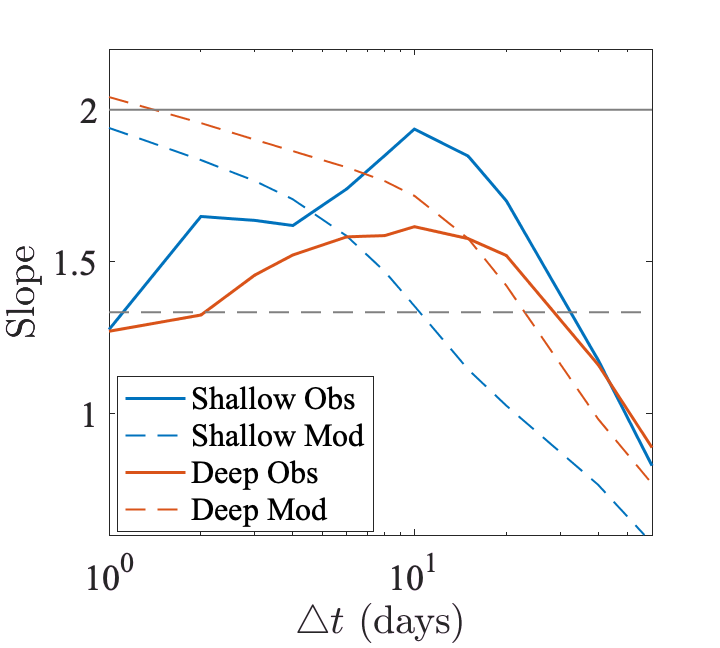

figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')
semilogx(dt, slope_obs_shallow, 'linewidth',1.5,'color', colors(col_num(1,1),:))
hold all
semilogx(dt, slope_mod_shallow, '--', 'linewidth',1.,'color', colors(col_num(1,1),:))
semilogx(dt, slope_obs, 'linewidth',1.5,'color', colors(col_num(2,1),:))
semilogx(dt, slope_mod, '--', 'linewidth',1.,'color', colors(col_num(2,1),:))


semilogx(dt, 2*dt./dt,  'linewidth',1.,'color',[0.5 0.5 0.5])
semilogx(dt, 4/3*dt./dt, '--',  'linewidth',1.,'color',[0.5 0.5 0.5])

axis([1 60 0.6 2.2])

legend({'Shallow Obs', 'Shallow Mod', 'Deep Obs', 'Deep Mod'}, 'location','best')

set(gca, 'fontsize', 18, 'fontname', 'times') 
ylabel('Slope', 'Interpreter','Latex')
xlabel('$\triangle t$ (days)', 'Interpreter','Latex')
print('rel_diff_slope.eps','-depsc')